# WIP

clear all
clc
close all

## Questão 1 A

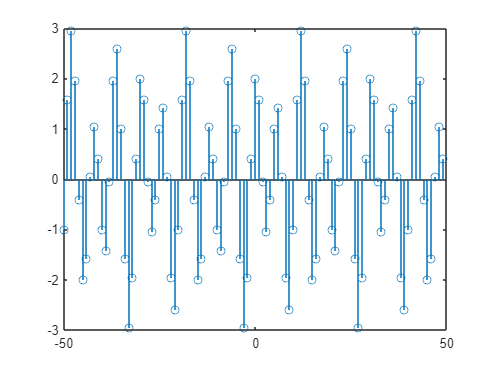

n = -50:1:49;
X = 2*cos(n*pi/3) + sin(n*pi/5);

figure
stem(n,X);

## B 1

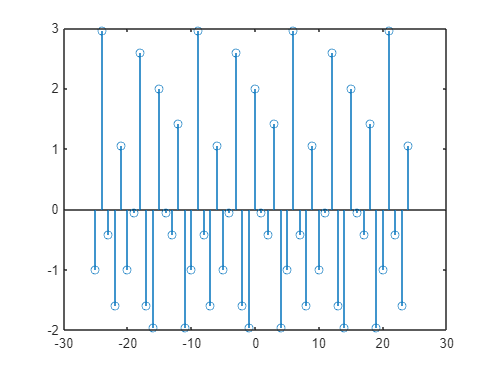

% cria o vetor Y1 e a sequencia n do Y1
Y1 = zeros(1,length(n)/2);
N1 = -25:1:24;

% a cada iteração pega o valor de x em 2*i
for i=1:length(Y1)
    Y1(i) = X(2*i-1);
end

figure
stem(N1,Y1);

## B 2

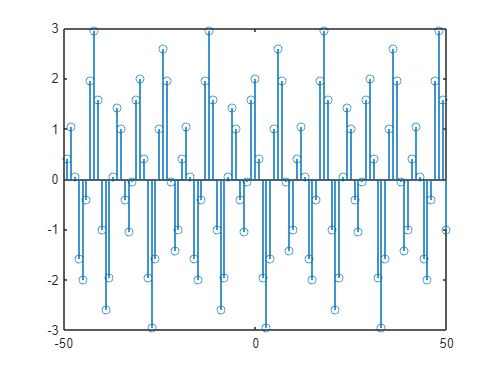

% cria o vetor Y2 e a sequencia n do Y2
Y2 = zeros(1,length(n));
N2 = -49:1:50;

% a cada iteração pega o valor de x em total - n,  ou seja, inverte ele
for i=1:length(Y2)
    Y2(i) = X((length(X) + 1) - i);
end

figure
stem(N2, Y2);

## B 3

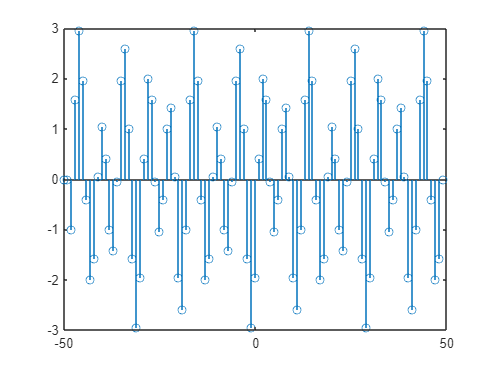

% cria o vetor Y3 e a sequencia N3
N3 = -50:1:49;
Y3 = zeros(1,length(n));

% a cada iteração pega o valor 
for i=3:length(X)-1
    Y3(i) = X(i-2);
end

figure
stem(N3,Y3);

## B 4

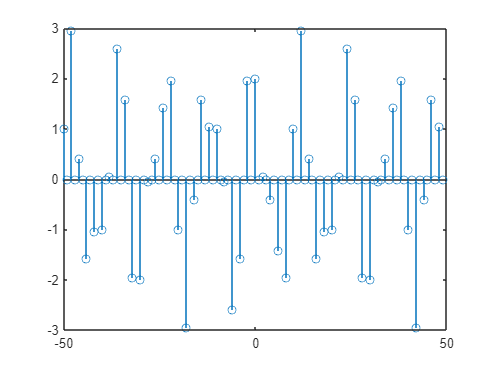

% cria o vetor Y4 e a sequencia N4
N4 = -50:1:49;
Y4 = zeros(1,length(n));

% cria um sinal auxiliar com a função cosseno
aux = cos(n*pi/2);
% faz a multiplicação
Y4 = X.*aux;

figure
stem(N4,Y4);

## B 5

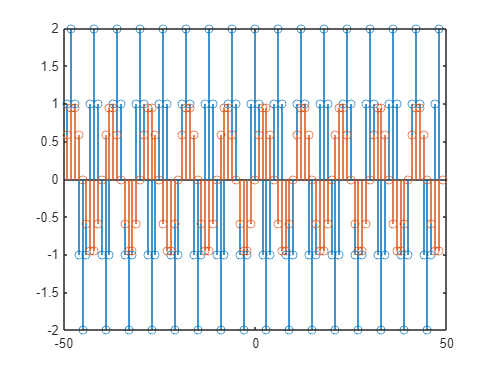

% cria os vetores par e impar e a sequencia n
N5 = -49:1:49;
Xeven = zeros(1,length(X)-1);
Xodd = zeros(1,length(X)-1);


% a cada iteração calcula o valor

for i = 1:length(X)-2
    Xeven(i) = (1/2)*(X(i+1) + X(101-i));
    Xodd(i) = (1/2)*(X(i+1) - X(101-i));
end

figure
stem(N5,Xeven);
hold all
stem(N5,Xodd);

## Questão 2

n = -50:1:49;
A = 0.5;
B = 2;


## X1 = impulso

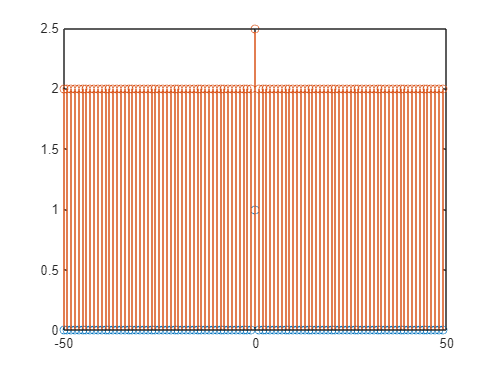

X1 = zeros(1, length(n));
X1(51) = 1;
Y1 = zeros(1,length(n));


Y1 = A*X1 + B;


figure
stem(n,X1);
hold all
stem(n,Y1);

## X1 = degrau

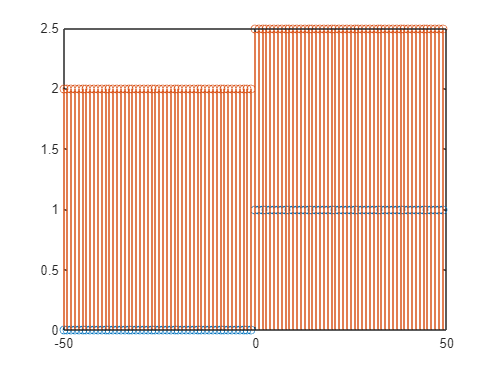

for i=1:length(n)/2
    X1(50+i) = 1;
end

Y1 = A*X1 + B;


figure
stem(n,X1);
hold all
stem(n,Y1);

## X1 = cosseno unitário

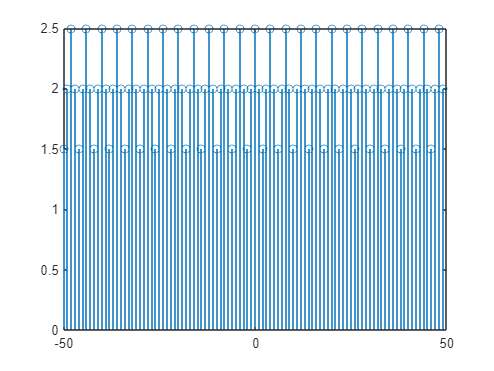

w = pi/2;

X1 =1*cos(w*n);
Y1 = A*X1 + B;


figure

stem(n,Y1);

## B Linearidade

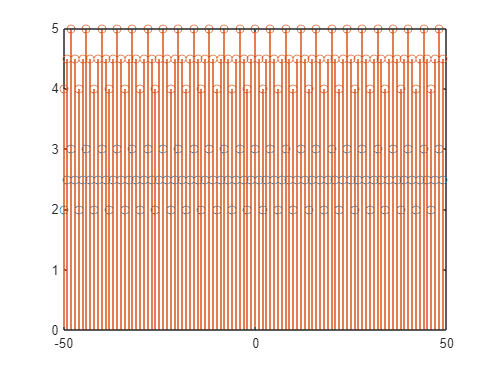

X1 = ones(1,length(n));
X2 = cos(w*n);

% aditividade 
Y1  = A.*(X1+X2) + B;
Y2 = (A.*X1 + B) + (A.*X2 + B);

figure
stem(n,Y1);
hold all
stem(n,Y2);

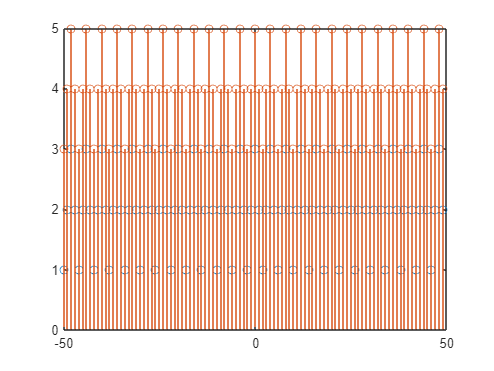

% Homogenidade

 X1 = cos(w*n);
 C = 2;

 Y1 = A.*(C.*X1) + B;

 Y2 = C*(A.*X1 + B);

figure
stem(n,Y1);
hold all
stem(n,Y2);

## Questão 3

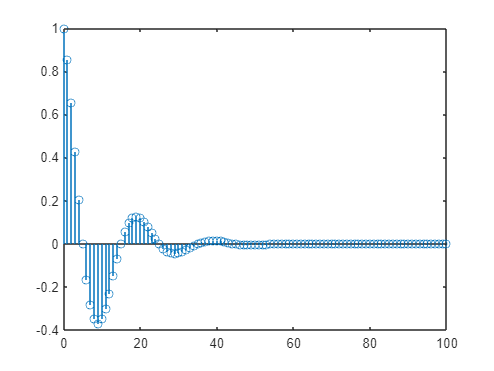

j = sqrt(-1);
e = 2.71828;
n = 0:1:100;
aux1 = (0.9).^n;
aux2 = e.^(j*(pi/10)*n);
X = aux1.*aux2;

% parte real

XR = real(X);
figure
stem(n,XR);

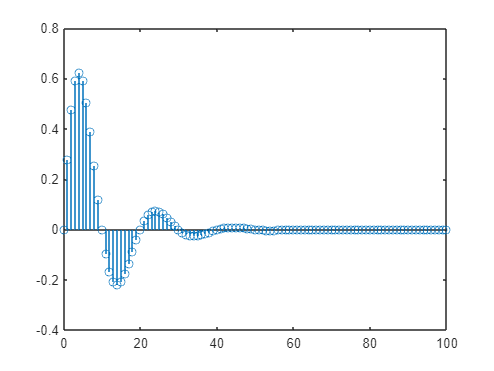


XI = imag(X);
figure
stem(n,XI);

## B Modulo e fase

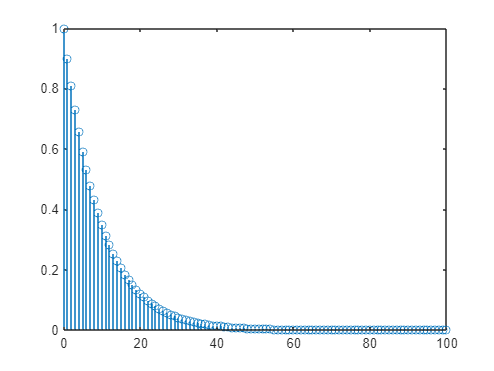


% Módulo
XM = abs(X);

figure
stem(n,XM);

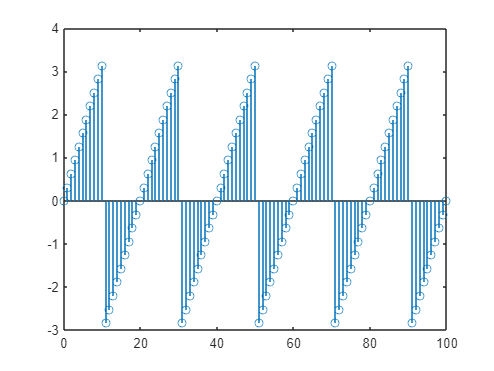

XA = angle(X);
figure
stem(n,XA);